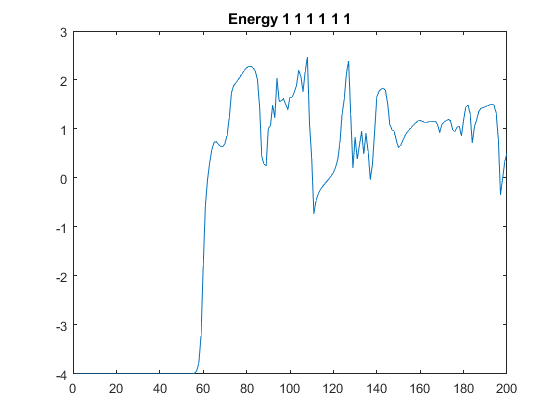

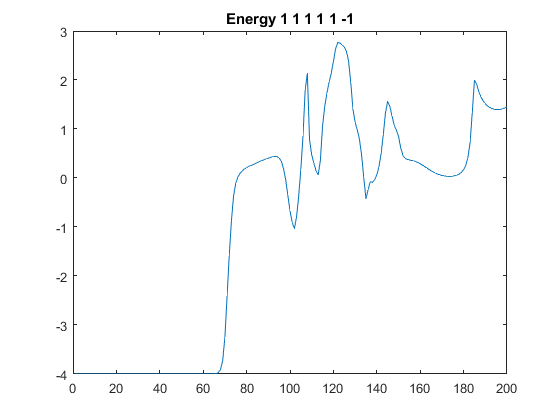

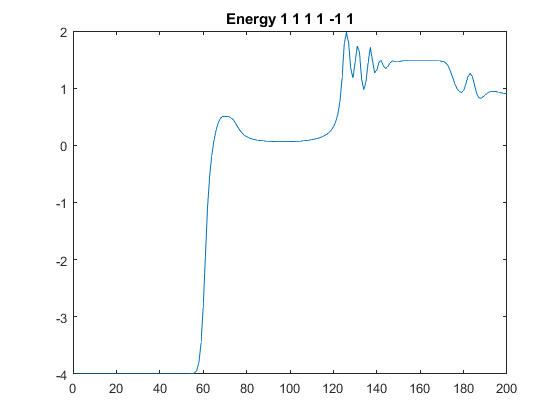

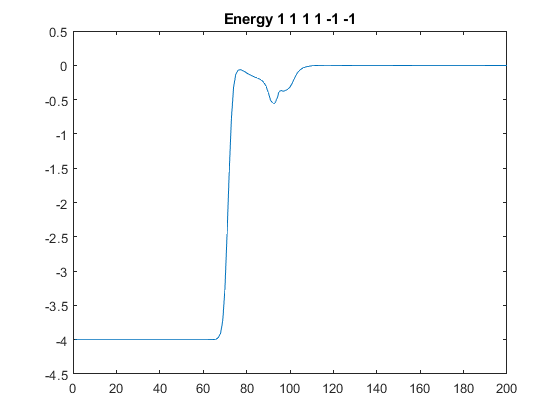

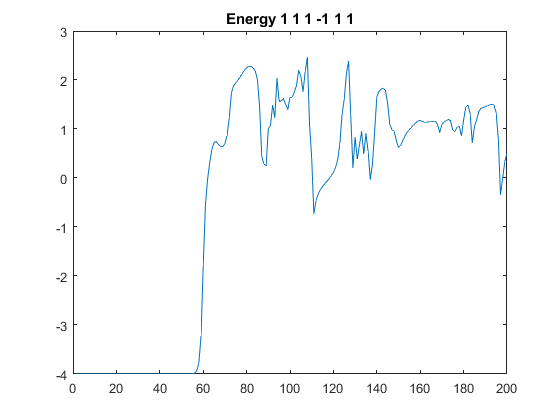

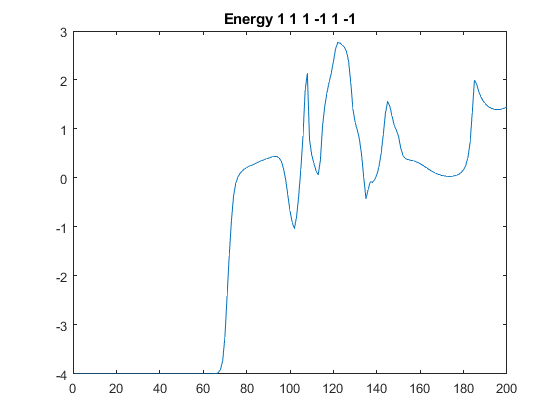

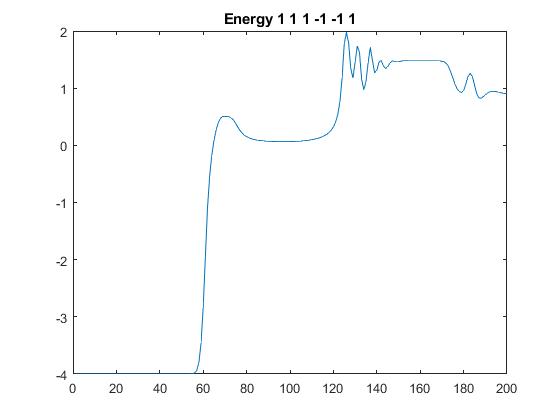

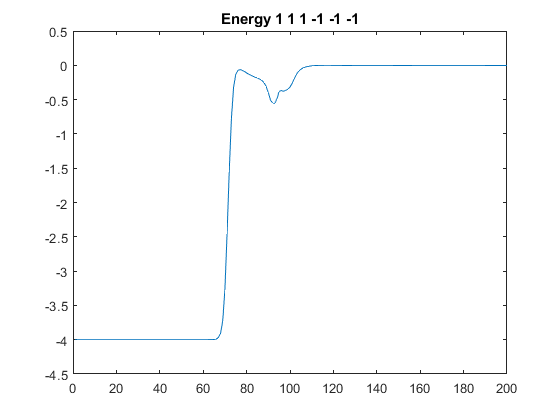

clc; clear;
rng(1);
for l=1:64
    N=4; M=4;
    w_mat = make_w(N,M);
    a_vec = make_a(N);
    b_vec = make_b(M);
    K=200;
    gamma=0.1;
    E=zeros(K,1);
    Ga=zeros(N,K);
    Gb=zeros(M,K);
    values=dec2spin(l,6);
    for k=1:K
        [E(k), Ga(:,k), Gb(:,k), Gw] = exactSampling(a_vec, b_vec, w_mat, @cluster, 0, 1);
        %    if norm(Ga)>1E-8
        %        return;
        %    end
        a_vec_real = real(a_vec) + values(1)*real(gamma*Ga(:,k));
        b_vec_real = real(b_vec) + values(2)*real(gamma*Gb(:,k));
        w_mat_real = real(w_mat) + values(3)*real(gamma*Gw);
        
        a_vec_imag = imag(a_vec) + values(4)*imag(gamma*Ga(:,k));
        b_vec_imag = imag(b_vec) + values(5)*imag(gamma*Gb(:,k));
        w_mat_imag = imag(w_mat) +   values(6)*imag(gamma*Gw);
        
        a_vec=a_vec_real+a_vec_imag*j;
        b_vec=b_vec_real+b_vec_imag*j;
        w_mat=w_mat_real+w_mat_imag*j;
        %    a_vec=round(a_vec,1);
        %    b_vec=round(b_vec,1);
        %    w_mat=round(w_mat,1);
        
        % a_vec=a_vec-gamma*Ga(:,k);
        % b_vec=b_vec-gamma*Gb(:,k);
        % w_mat=w_mat-gamma*Gw;
    end
    %
    figure;
    plot(E);
title(["Energy "+num2str(values(1))+" "+num2str(values(2))+" "+num2str(values(3))+" "+num2str(values(4))+" "+num2str(values(5))+" "+num2str(values(6))])
end